## **HCP Main Sample - External Validation 'Basic NMA Model' in HCP Lockbox Sample **

Conduction of the external cross-validation of the 'Basic NMA Model' that is built using two input predictor variables. The predictor variables are derived from individual's coupling values and extracted by using group-based positive and negative NMA masks. The script contains three parts: **Part 1 **partitions the sample into five different folds (considering family relations and intelligence distribution) and creates a positive and negative NMAs for each training fold (4/5 partition) and test fold (in this case the lockbox sample). **Part 2 **uses the NMAs created in part 1 to build multiple linear regression models that are then tested for their ability to predict general intelligence in the test samples (lockbox sample in this case). **Part 3 **assesses the significance of the prediction model with a permutation test. 

Before running this script:

- run all scripts in HCP Data Prep 

**Part 1**

Partitioning the sample into 5 different folds and creating the positive and negative NMAs for each training fold and test fold (in this case the lockbox sample) based on the correllation with general intelligence scores. 

**1. Prepare the coupling data for the HCP main sample **

1.1. Create a cell that contains for each subject a vector of 8 predictors for each node 

for i = 1:532
    x = final_r_all_HCP_relational_532{i,1}; % change input data here based on the investigated condition
    for j = 1:358
    Node_all_baseline_HCP{i,j} = x(j,:);
    end
end

1.2. Create cell that contains information from all subjects and all coupling measures for all nodes separetely (532*8)

% extract for each collumn 8 rows from each row and put them together in a matrix (--> I need 532*8 matrix for each node)

n = size(Node_all_baseline_HCP,2);
All_Nodes_complete_HCP = cell(1,n);
for j = 1:n
    All_Nodes_complete_HCP{j} = vertcat(Node_all_baseline_HCP{:,j});
end 

1.3. Only keep 4 measures: Path Length (1), Communicability (2), Cosine Distance (3), & Search Information (4)

for i = 1:358
    eight_measures_per_node = All_Nodes_complete_HCP{1,i};
    four_measures_per_node = eight_measures_per_node(:,1:4);
    All_Nodes_complete_HCP_4_measures{1,i} = four_measures_per_node;
end

**2. Prepare the coupling data for the HCP lockbox sample **

2.1.  Create a cell that contains for each subject a vector of 8 predictors for each node

for i = 1:232
    x = final_r_all_HCP_relational_232{i,1};
    for j = 1:358
    Node_all_baseline_HCP_lockbox_weighted_only{i,j} = x(j,:);
    end
end

2.2.  Create cell that contains information from all subjects and all coupling measures for all nodes separetely (232*8)

% extract for each collumn 8 rows from each row and put them together in a matrix (--> I need 232*8 matrix for each node)

n = size(Node_all_baseline_HCP_lockbox_weighted_only,2);
All_Nodes_complete_baseline_HCP_lockbox_weighted_only = cell(1,n);
for j = 1:n
    All_Nodes_complete_baseline_HCP_lockbox_weighted_only{j} = vertcat(Node_all_baseline_HCP_lockbox_weighted_only{:,j});
end 

2.3. Only keep 4 measures: Path Length (1), Communicability (2), Cosine Distance (3) & Search Information (4) 

for i = 1:358
    eight_measures_per_node =  All_Nodes_complete_baseline_HCP_lockbox_weighted_only{1,i};
    four_measures_per_node_lockbox = eight_measures_per_node(:,1:4);
    All_Nodes_complete_baseline_HCP_lockbox_4_measures{1,i} = four_measures_per_node_lockbox;
end

**3. Split sample into 5 folds **

3.1. Create a loop to do the partition 100 times 

for cross_validation_round = 1:100
    display(cross_validation_round)

cross_validation_round = 1

cross_validation_round = 2

cross_validation_round = 3

cross_validation_round = 4

cross_validation_round = 5

cross_validation_round = 6

cross_validation_round = 7

cross_validation_round = 8

cross_validation_round = 9

cross_validation_round = 10

cross_validation_round = 11

cross_validation_round = 12

cross_validation_round = 13

cross_validation_round = 14

cross_validation_round = 15

cross_validation_round = 16

cross_validation_round = 17

cross_validation_round = 18

cross_validation_round = 19

cross_validation_round = 20

cross_validation_round = 21

cross_validation_round = 22

cross_validation_round = 23

cross_validation_round = 24

cross_validation_round = 25

cross_validation_round = 26

cross_validation_round = 27

cross_validation_round = 28

cross_validation_round = 29

cross_validation_round = 30

cross_validation_round = 31

cross_validation_round = 32

cross_validation_round = 33

cross_validation_round = 34

cross_validation_round = 35

cross_validation_round = 36

cross_validation_round = 37

cross_validation_round = 38

cross_validation_round = 39

cross_validation_round = 40

cross_validation_round = 41

cross_validation_round = 42

cross_validation_round = 43

cross_validation_round = 44

cross_validation_round = 45

cross_validation_round = 46

cross_validation_round = 47

cross_validation_round = 48

cross_validation_round = 49

cross_validation_round = 50

cross_validation_round = 51

cross_validation_round = 52

cross_validation_round = 53

cross_validation_round = 54

cross_validation_round = 55

cross_validation_round = 56

cross_validation_round = 57

cross_validation_round = 58

cross_validation_round = 59

cross_validation_round = 60

cross_validation_round = 61

cross_validation_round = 62

cross_validation_round = 63

cross_validation_round = 64

cross_validation_round = 65

cross_validation_round = 66

cross_validation_round = 67

cross_validation_round = 68

cross_validation_round = 69

cross_validation_round = 70

cross_validation_round = 71

cross_validation_round = 72

cross_validation_round = 73

cross_validation_round = 74

cross_validation_round = 75

cross_validation_round = 76

cross_validation_round = 77

cross_validation_round = 78

cross_validation_round = 79

cross_validation_round = 80

cross_validation_round = 81

cross_validation_round = 82

cross_validation_round = 83

cross_validation_round = 84

cross_validation_round = 85

cross_validation_round = 86

cross_validation_round = 87

cross_validation_round = 88

cross_validation_round = 89

cross_validation_round = 90

cross_validation_round = 91

cross_validation_round = 92

cross_validation_round = 93

cross_validation_round = 94

cross_validation_round = 95

cross_validation_round = 96

cross_validation_round = 97

cross_validation_round = 98

cross_validation_round = 99

cross_validation_round = 100

3.2. Create a cross-validation partition based on family IQ

This part of the script creates a partition for the external cross validation of the linear regression model that is stratified based on family IQ. That way, we respect the family structures in the HCP and create a distribution of subjects in the and training samples that is not biased towards general intelligence scores. 

3.2.1. Assign the variables

HCP_family_ID = HCP_behavioral_532.Family_ID;
HCP_subject_names = HCP_behavioral_532.("Subject Name");
HCP_intelligence_score = HCP_behavioral_532.gscore;

3.2.2. Create a table containing all the information that I need 

[number_of_families,~,family_group_number] = unique(HCP_behavioral_532.Family_ID); 
% there are 268 families in the main main sample (unique output 1)

for i = 1:268 % because there is 268 families in the sample (unique output 1) 
    
    indices_for_same_family = find(family_group_number == i);
    subject_ID_same_fam = HCP_subject_names(indices_for_same_family);
    family_ID_original = HCP_family_ID(indices_for_same_family);
    intelligence_score_same_fam = HCP_intelligence_score(indices_for_same_family);
    
    family_info_HCP{i,1} = i;
    family_info_HCP{i,2} = family_ID_original;
    family_info_HCP{i,3} = indices_for_same_family;
    family_info_HCP{i,4} = subject_ID_same_fam;
    family_info_HCP{i,5} = intelligence_score_same_fam;
    
end

3.2.3. Create a family intelligence score

for i = 1:268
    family_intelligence_separate = family_info_HCP{i,5};
    family_intelligence_average = mean(family_intelligence_separate);
    family_info_HCP{i,6} = family_intelligence_average;
end

3.2.4. Convert cell to table

family_info_HCP_table = cell2table(family_info_HCP);
family_info_HCP_table.Properties.VariableNames = {'Group Number','Original_Family_ID', 'Indices_for_same_Family', 'Subject_ID_same_fam', 'intelligence_score_separate_same_fam', 'Mean_intelligence_score_same_fam'};

3.2.5. Create a CV partition based on family IQ (for the families) 

Family_intelligence = family_info_HCP_table.Mean_intelligence_score_same_fam;


Intelligence_for_cv_partition_1 = rescale(Family_intelligence,1,30);
Intelligence_for_cv_partition = int16(Intelligence_for_cv_partition_1); % create 30 groups to ultimatly create a stratified cv partition


c = cvpartition(Intelligence_for_cv_partition,'KFold',5);

3.2.6. Create output: indices for the families

% Train 1 & Test 1 

index_test_1 = find(test(c,1));
index_train_1 = find(training(c,1));

% Train 2 & Test 2 
index_test_2 = find(test(c,2));
index_train_2 = find(training(c,2));

% Train 3 & Test 3 

index_test_3 = find(test(c,3));
index_train_3 = find(training(c,3));

% Train 4 & Test 4 

index_test_4 = find(test(c,4));
index_train_4 = find(training(c,4));

% Train 5 & Test 5 

index_test_5 = find(test(c,5));
index_train_5 = find(training(c,5));

3.2.7. Reassign the individual subjects back into the groups from the partition 

% Train 1 & Test 1 

test_1 = family_info_HCP_table.Indices_for_same_Family(index_test_1);
index_test_1_fam = cat(1,test_1{:,1});
index_test_1_fam = sort(index_test_1_fam,"ascend");

train_1 = family_info_HCP_table.Indices_for_same_Family(index_train_1);
index_train_1_fam = cat(1,train_1{:,1});
index_train_1_fam = sort(index_train_1_fam,"ascend");

% Train 2 & Test 2 

test_2 = family_info_HCP_table.Indices_for_same_Family(index_test_2);
index_test_2_fam = cat(1,test_2{:,1});
index_test_2_fam = sort(index_test_2_fam,"ascend");

train_2 = family_info_HCP_table.Indices_for_same_Family(index_train_2);
index_train_2_fam = cat(1,train_2{:,1});
index_train_2_fam = sort(index_train_2_fam,"ascend");


% Train 3 & Test 3 

test_3 = family_info_HCP_table.Indices_for_same_Family(index_test_3);
index_test_3_fam = cat(1,test_3{:,1});
index_test_3_fam = sort(index_test_3_fam,"ascend");

train_3 = family_info_HCP_table.Indices_for_same_Family(index_train_3);
index_train_3_fam = cat(1,train_3{:,1});
index_train_3_fam = sort(index_train_3_fam,"ascend");


% Train 4 & Test 4 

test_4 = family_info_HCP_table.Indices_for_same_Family(index_test_4);
index_test_4_fam = cat(1,test_4{:,1});
index_test_4_fam = sort(index_test_4_fam,"ascend");

train_4 = family_info_HCP_table.Indices_for_same_Family(index_train_4);
index_train_4_fam = cat(1,train_4{:,1});
index_train_4_fam = sort(index_train_4_fam,"ascend");


% Train 5 & Test 5 

test_5 = family_info_HCP_table.Indices_for_same_Family(index_test_5);
index_test_5_fam = cat(1,test_5{:,1});
index_test_5_fam = sort(index_test_5_fam,"ascend");

train_5 = family_info_HCP_table.Indices_for_same_Family(index_train_5);
index_train_5_fam = cat(1,train_5{:,1});
index_train_5_fam = sort(index_train_5_fam,"ascend");

% done with creating the training/test partition

3.3.  Divide data in test and training samples 

3.3.1. Divide the coupling data into 5 training samples (test sets are not necessary)

for i = 1:358
   all_data_node = All_Nodes_complete_HCP_4_measures{1,i};
   
   Node_training_sample_1 = all_data_node(index_train_1_fam,:);
   Node_test_sample_1 = all_data_node(index_test_1_fam,:);
   
   Node_training_sample_2 = all_data_node(index_train_2_fam,:);
   Node_test_sample_2 = all_data_node(index_test_2_fam,:);
   
   Node_training_sample_3 = all_data_node(index_train_3_fam,:);
   Node_test_sample_3 = all_data_node(index_test_3_fam, :);
   
   Node_training_sample_4 = all_data_node(index_train_4_fam,:);
   Node_test_sample_4 = all_data_node(index_test_4_fam,:);
   
   Node_training_sample_5 = all_data_node(index_train_5_fam,:);
   Node_test_sample_5 = all_data_node(index_test_5_fam, :);
   
   All_Nodes_complete_cross_validation_HCP_{1,i} = Node_training_sample_1;
   All_Nodes_complete_cross_validation_HCP_{2,i} = Node_training_sample_2;
   All_Nodes_complete_cross_validation_HCP_{3,i} = Node_training_sample_3;
   All_Nodes_complete_cross_validation_HCP_{4,i} = Node_training_sample_4;
   All_Nodes_complete_cross_validation_HCP_{5,i} = Node_training_sample_5;
   All_Nodes_complete_cross_validation_HCP_{6,i} = Node_test_sample_1;
   All_Nodes_complete_cross_validation_HCP_{7,i} = Node_test_sample_2;
   All_Nodes_complete_cross_validation_HCP_{8,i} = Node_test_sample_3;
   All_Nodes_complete_cross_validation_HCP_{9,i} = Node_test_sample_4;
   All_Nodes_complete_cross_validation_HCP_{10,i} = Node_test_sample_5;
   
end

3.3.2.  Divide intelligence into 5 training samples 

Intelligence = HCP_behavioral_532.gscore;
Intelligence_lockbox = HCP_behavioral_232.gscore;

Intelligence_train_1 = Intelligence(index_train_1_fam,:);
Intelligence_train_2 = Intelligence(index_train_2_fam,:);
Intelligence_train_3 = Intelligence(index_train_3_fam,:);
Intelligence_train_4 = Intelligence(index_train_4_fam,:);
Intelligence_train_5 = Intelligence(index_train_5_fam,:);

Intelligence_training_samples{1,:} = Intelligence_train_1;
Intelligence_training_samples{2,:} = Intelligence_train_2;
Intelligence_training_samples{3,:} = Intelligence_train_3;
Intelligence_training_samples{4,:} = Intelligence_train_4;
Intelligence_training_samples{5,:} = Intelligence_train_5;

3.3.3.  Divide confounding variables into 5 training samples

Age = HCP_behavioral_532.Age_in_Yrs;
Age_lockbox = HCP_behavioral_232.Age_in_Yrs;

Age_train_1 = Age(index_train_1_fam,:);
Age_train_2 = Age(index_train_2_fam,:);
Age_train_3 = Age(index_train_3_fam,:);
Age_train_4 = Age(index_train_4_fam,:);
Age_train_5 = Age(index_train_5_fam,:);

Age_training_samples{1,:} = Age_train_1;
Age_training_samples{2,:} = Age_train_2;
Age_training_samples{3,:} = Age_train_3;
Age_training_samples{4,:} = Age_train_4;
Age_training_samples{5,:} = Age_train_5;

Gender = HCP_behavioral_532.gender_num;
Gender_lockbox = HCP_behavioral_232.gender_num;

Gender_train_1 = Gender(index_train_1_fam,:);
Gender_train_2 = Gender(index_train_2_fam,:);
Gender_train_3 = Gender(index_train_3_fam,:);
Gender_train_4 = Gender(index_train_4_fam,:);
Gender_train_5 = Gender(index_train_5_fam,:);

Gender_training_samples{1,:} = Gender_train_1;
Gender_training_samples{2,:} = Gender_train_2;
Gender_training_samples{3,:} = Gender_train_3;
Gender_training_samples{4,:} = Gender_train_4;
Gender_training_samples{5,:} = Gender_train_5;

meanFDJenk = HCP_behavioral_532.mean_mean_RMS_relational;
meanFDJenk_lockbox = HCP_behavioral_232.mean_mean_RMS_relational;

meanFDJenk_train_1 = meanFDJenk(index_train_1_fam,:);
meanFDJenk_train_2 = meanFDJenk(index_train_2_fam,:);
meanFDJenk_train_3 = meanFDJenk(index_train_3_fam,:);
meanFDJenk_train_4 = meanFDJenk(index_train_4_fam,:);
meanFDJenk_train_5 = meanFDJenk(index_train_5_fam,:);

meanFDJenk_training_samples{1,:} = meanFDJenk_train_1;
meanFDJenk_training_samples{2,:} = meanFDJenk_train_2;
meanFDJenk_training_samples{3,:} = meanFDJenk_train_3;
meanFDJenk_training_samples{4,:} = meanFDJenk_train_4;
meanFDJenk_training_samples{5,:} = meanFDJenk_train_5;

LQ = HCP_behavioral_532.Handedness;
LQ_lockbox = HCP_behavioral_232.Handedness;

LQ_train_1 = LQ(index_train_1_fam,:);
LQ_train_2 = LQ(index_train_2_fam,:);
LQ_train_3 = LQ(index_train_3_fam,:);
LQ_train_4 = LQ(index_train_4_fam,:);
LQ_train_5 = LQ(index_train_5_fam,:);

LQ_training_samples{1,:} = LQ_train_1;
LQ_training_samples{2,:} = LQ_train_2;
LQ_training_samples{3,:} = LQ_train_3;
LQ_training_samples{4,:} = LQ_train_4;
LQ_training_samples{5,:} = LQ_train_5;

3.4. Build a positive and negative node measure assignment (NMA) for each training sample

3.4.1. Build a correlation matrix for each training fold 


for fold = 1:5
    
Correlation_com_measures_fold_rho = zeros(358,4); % Preallocation
Correlation_com_measure_fold_pval = zeros(358,4); % Preallocation
    
for i = 1:358 % mache das für jede Node Extra
    All_Communication_measures_per_node = All_Nodes_complete_cross_validation_HCP_{fold,i};
    
     for p = 1:4 % correlate each measure with intelligence
        Communication_Measure_separate = All_Communication_measures_per_node(:,p);
        
             % Correlation

                x = [Communication_Measure_separate, Intelligence_training_samples{fold}];
                z = [Age_training_samples{fold}, Gender_training_samples{fold}, meanFDJenk_training_samples{fold}, LQ_training_samples{fold}]; % control variables
   
                [rho,pval] = partialcorr(x,z);
                
                rho = rho(1,2);
                pval = pval(1,2);
            
               Correlation_com_measures_fold_rho(i,p) = rho;
               Correlation_com_measure_fold_pval(i,p) = pval;

               
    end
end

Correlation_matrices_all_folds{fold,1} = Correlation_com_measures_fold_rho;
Correlation_matrices_all_folds{fold,2} = Correlation_com_measure_fold_pval;
end

3.4.2. Find out which ones correlate the most positive with intelligence

for fold = 1:5
    Correlation_com_measures_fold_rho = Correlation_matrices_all_folds{fold,1};
for i = 1:358
    Correlation_rho_per_node = Correlation_com_measures_fold_rho(i,:);
    Max_Rho = max(Correlation_rho_per_node);
    Idx_max_rho = find(Correlation_rho_per_node == Max_Rho);
    Info_best_performing_communication_measure_pos_train_rho{i,1} = Max_Rho;
    Info_best_performing_communication_measure_pos_train_idx{i,1} = Idx_max_rho;
end
Pos_NMA_all_fold{fold,1} = Info_best_performing_communication_measure_pos_train_rho;
Pos_NMA_all_fold{fold,2} = Info_best_performing_communication_measure_pos_train_idx;
end

3.4.3. Find out which ones correlate the most negative with intelligence

for fold = 1:5
    Correlation_com_measures_fold_rho = Correlation_matrices_all_folds{fold,1};

for i = 1:358
    Correlation_rho_per_node = Correlation_com_measures_fold_rho(i,:);
    Min_Rho = min(Correlation_rho_per_node);
    Idx_min_rho = find(Correlation_rho_per_node == Min_Rho);
    Info_best_performing_communication_measure_neg_train_rho{i,1} = Min_Rho;
    Info_best_performing_communication_measure_neg_train_idx{i,1} = Idx_min_rho;
end
Neg_NMA_all_fold{fold,1} = Info_best_performing_communication_measure_neg_train_rho;
Neg_NMA_all_fold{fold,2} = Info_best_performing_communication_measure_neg_train_idx;
end

3.4.4. Define sizes of training samples

size_training_sample_1 = size(All_Nodes_complete_cross_validation_HCP_{1,1},1);
size_training_sample_2 = size(All_Nodes_complete_cross_validation_HCP_{2,1},1);
size_training_sample_3 = size(All_Nodes_complete_cross_validation_HCP_{3,1},1);
size_training_sample_4 = size(All_Nodes_complete_cross_validation_HCP_{4,1},1);
size_training_sample_5 = size(All_Nodes_complete_cross_validation_HCP_{5,1},1);


size_training_test_samples{1,1} = size_training_sample_1;
size_training_test_samples{2,1} = size_training_sample_2;
size_training_test_samples{3,1} = size_training_sample_3;
size_training_test_samples{4,1} = size_training_sample_4;
size_training_test_samples{5,1} = size_training_sample_5;

3.4.5. Extract the NMA values for the positive NMA

for fold = 1:5

size_sample = size_training_test_samples{fold,1};     
Best_case_scenario_r_values_pos_train = zeros(358,size_sample);
best_performing_measure_per_node_pos = cell2mat(Pos_NMA_all_fold{fold,2});

for i = 1:358
    index = best_performing_measure_per_node_pos(i);
    Best_scenario_node_values_pos = All_Nodes_complete_cross_validation_HCP_{fold,i}(:,index); 
    Best_case_scenario_r_values_pos_train(i,:) = Best_scenario_node_values_pos';
end

Best_case_scenario_r_values_pos_train = Best_case_scenario_r_values_pos_train';

Best_case_scenario_training_samples{fold,1} = Best_case_scenario_r_values_pos_train;

end 

3.4.6. Extract the NMA values for the negative NMA

for fold = 1:5
   
size_sample = size_training_test_samples{fold,1};
Best_case_scenario_r_values_neg_train = zeros(358,size_sample);
best_performing_measure_per_node_neg = cell2mat(Neg_NMA_all_fold{fold,2});

for i = 1:358
    index = best_performing_measure_per_node_neg(i);
    Best_scenario_node_values_neg = All_Nodes_complete_cross_validation_HCP_{fold,i}(:,index);
    Best_case_scenario_r_values_neg_train(i,:) = Best_scenario_node_values_neg';
end

Best_case_scenario_r_values_neg_train = Best_case_scenario_r_values_neg_train';

Best_case_scenario_training_samples{fold,2} = Best_case_scenario_r_values_neg_train;

end 

**Lockbox Sample **

3.5.  Build a positive and negative node measure assignment (NMA) for each 'Test Fold' -->  Take data from lockbox sample!

3.5.1.  Extract the NMA values for the positive NMA

for fold = 1:5
    size_sample = 232;
    Best_case_scenario_r_values_pos_test = zeros(358,size_sample);
    best_performing_measure_per_node_pos = cell2mat(Pos_NMA_all_fold{fold,2});
    

for i = 1:358 
    index = best_performing_measure_per_node_pos(i);
    Best_scenario_node_values_pos = All_Nodes_complete_baseline_HCP_lockbox_4_measures{1,i}(:,index);
    Best_case_scenario_r_values_pos_test(i,:) = Best_scenario_node_values_pos';
end

Best_case_scenario_r_values_pos_test = Best_case_scenario_r_values_pos_test';

Best_case_scenario_test_samples{fold,1} = Best_case_scenario_r_values_pos_test;

end

3.5.2.  Extract the NMA values for the negative NMA

for fold = 1:5
    size_sample = 232;
    Best_case_scenario_r_values_neg_test = zeros(358,size_sample);
    best_performing_measure_per_node_neg = cell2mat(Neg_NMA_all_fold{fold,2});

for i = 1:358 
    index = best_performing_measure_per_node_neg(i);
    Best_scenario_node_values_neg = All_Nodes_complete_baseline_HCP_lockbox_4_measures{1,i}(:,index);
    Best_case_scenario_r_values_neg_test(i,:) = Best_scenario_node_values_neg';
end

Best_case_scenario_r_values_neg_test = Best_case_scenario_r_values_neg_test';

Best_case_scenario_test_samples{fold,2} = Best_case_scenario_r_values_neg_test;

end

**Part 2:**

Use node-measure assignments created above to build multiple linear regression model in training samples and test it in lockbox sample. 

**1. Build the models for the training samples **

1.1. Training Sample 1

Regress out the confounding variables from intelligence and normalize the residuals

confounds = [Age_train_1 Gender_train_1 meanFDJenk_train_1 LQ_train_1];

mdl_regress_train_1_intelligence = fitlm(confounds,Intelligence_train_1);
residuals_intelligence_train_1 = mdl_regress_train_1_intelligence.Residuals.Raw;

[residuals_intelligence_train_1_z,c_intelligence_train_1,s_intelligence_train_1] = normalize(residuals_intelligence_train_1);

Retrieve NMA for the subjects

Best_case_scenario_r_values_pos = Best_case_scenario_training_samples{1,1};
Best_case_scenario_r_values_neg = Best_case_scenario_training_samples{1,2};

Take the mean per subject 

Positive_all = nanmean(Best_case_scenario_r_values_pos,2);
Negative_all = nanmean(Best_case_scenario_r_values_neg,2);

Regress out the confounding variables from positive and negative NMA and normalize the residuals

confounds = [Age_train_1 Gender_train_1 meanFDJenk_train_1 LQ_train_1];

mdl_regress_train_1_pos_bcs = fitlm(confounds,Positive_all);
residuals_pos_train_1 = mdl_regress_train_1_pos_bcs.Residuals.Raw;

[residuals_pos_train_1_z, c_pos_NMA_train_1, s_pos_NMA_train_1] = normalize(residuals_pos_train_1);

mdl_regress_train_1_neg_bcs = fitlm(confounds,Negative_all);
residuals_neg_train_1 = mdl_regress_train_1_neg_bcs.Residuals.Raw;

[residuals_neg_train_1_z, c_neg_NMA_train_1, s_neg_NMA_train_1] = normalize(residuals_neg_train_1);

Build the actual model

Model_Matrix = [residuals_pos_train_1_z residuals_neg_train_1_z residuals_intelligence_train_1_z];
Model_Matrix = num2cell(Model_Matrix);
Model_Matrix_table = cell2table(Model_Matrix);
Model_Matrix_table.Properties.VariableNames = {'residuals_pos_train_1_z', 'residuals_neg_train_1_z','Residuals_intelligence_train_1_z'};

mdl_pos_neg_bcs_train_1 = fitlm(Model_Matrix_table);
plot(mdl_pos_neg_bcs_train_1);

1.2. Training Sample 2

Regress out the confounding variables from intelligence and normalize the residuals

confounds = [Age_train_2 Gender_train_2 meanFDJenk_train_2 LQ_train_2];

mdl_regress_train_2_intelligence = fitlm(confounds,Intelligence_train_2);
residuals_intelligence_train_2 = mdl_regress_train_2_intelligence.Residuals.Raw;

[residuals_intelligence_train_2_z,c_intelligence_train_2,s_intelligence_train_2] = normalize(residuals_intelligence_train_2);

Retrieve NMA for the subjects

Best_case_scenario_r_values_pos = Best_case_scenario_training_samples{2,1};
Best_case_scenario_r_values_neg = Best_case_scenario_training_samples{2,2};

Take the mean per subject

Positive_all = nanmean(Best_case_scenario_r_values_pos,2);
Negative_all = nanmean(Best_case_scenario_r_values_neg,2);

Regress out the confounding variables from positive and negative NMA and normalize the residuals

confounds = [Age_train_2 Gender_train_2 meanFDJenk_train_2 LQ_train_2];

mdl_regress_train_2_pos_bcs = fitlm(confounds,Positive_all);
residuals_pos_train_2 = mdl_regress_train_2_pos_bcs.Residuals.Raw;

[residuals_pos_train_2_z, c_pos_NMA_train_2, s_pos_NMA_train_2] = normalize(residuals_pos_train_2);

mdl_regress_train_2_neg_bcs = fitlm(confounds,Negative_all);
residuals_neg_train_2 = mdl_regress_train_2_neg_bcs.Residuals.Raw;

[residuals_neg_train_2_z, c_neg_NMA_train_2, s_neg_NMA_train_2] = normalize(residuals_neg_train_2);

Build the actual model

Model_Matrix = [residuals_pos_train_2_z residuals_neg_train_2_z residuals_intelligence_train_2_z];
Model_Matrix = num2cell(Model_Matrix);
Model_Matrix_table = cell2table(Model_Matrix);
Model_Matrix_table.Properties.VariableNames = {'residuals_pos_train_2_z','residuals_neg_train_2_z','Residuals_intelligence_train_2_z'};

mdl_pos_neg_bcs_train_2 = fitlm(Model_Matrix_table);
plot(mdl_pos_neg_bcs_train_2);

1.3. Training Sample 3

Regress out the confounding variables from intelligence and normalize the residuals

confounds = [Age_train_3 Gender_train_3 meanFDJenk_train_3 LQ_train_3];

mdl_regress_train_3_intelligence = fitlm(confounds,Intelligence_train_3);
residuals_intelligence_train_3 = mdl_regress_train_3_intelligence.Residuals.Raw;

[residuals_intelligence_train_3_z,c_intelligence_train_3,s_intelligence_train_3] = normalize(residuals_intelligence_train_3);

Retrieve NMA for the subjects 

Best_case_scenario_r_values_pos = Best_case_scenario_training_samples{3,1};
Best_case_scenario_r_values_neg = Best_case_scenario_training_samples{3,2};

Take the mean per subject

Positive_all = nanmean(Best_case_scenario_r_values_pos,2);
Negative_all = nanmean(Best_case_scenario_r_values_neg,2);

Regress out the confounding variables from positive and negative NMA  and normalize the residuals

confounds = [Age_train_3 Gender_train_3 meanFDJenk_train_3 LQ_train_3];

mdl_regress_train_3_pos_bcs = fitlm(confounds,Positive_all);
residuals_pos_train_3 = mdl_regress_train_3_pos_bcs.Residuals.Raw;

[residuals_pos_train_3_z, c_pos_NMA_train_3, s_pos_NMA_train_3] = normalize(residuals_pos_train_3);

mdl_regress_train_3_neg_bcs = fitlm(confounds,Negative_all);
residuals_neg_train_3 = mdl_regress_train_3_neg_bcs.Residuals.Raw;

[residuals_neg_train_3_z, c_neg_NMA_train_3, s_neg_NMA_train_3] = normalize(residuals_neg_train_3);

Build the actual model

Model_Matrix = [residuals_pos_train_3_z residuals_neg_train_3_z residuals_intelligence_train_3_z];
Model_Matrix = num2cell(Model_Matrix);
Model_Matrix_table = cell2table(Model_Matrix);
Model_Matrix_table.Properties.VariableNames = {'residuals_pos_train_3_z', 'residuals_neg_train_3_z','Residuals_intelligence_train_3_z'};

mdl_pos_neg_bcs_train_3 = fitlm(Model_Matrix_table);
plot(mdl_pos_neg_bcs_train_3);


1.4. Training Sample 4

Regress out the confounding variables from intelligence and normalize the residuals

confounds = [Age_train_4 Gender_train_4 meanFDJenk_train_4 LQ_train_4];

mdl_regress_train_4_intelligence = fitlm(confounds,Intelligence_train_4);
residuals_intelligence_train_4 = mdl_regress_train_4_intelligence.Residuals.Raw;

[residuals_intelligence_train_4_z,c_intelligence_train_4,s_intelligence_train_4] = normalize(residuals_intelligence_train_4);

Retrieve NMA for the subjects

Best_case_scenario_r_values_pos = Best_case_scenario_training_samples{4,1};
Best_case_scenario_r_values_neg = Best_case_scenario_training_samples{4,2};

Take the mean per subject 

Positive_all = nanmean(Best_case_scenario_r_values_pos,2);
Negative_all = nanmean(Best_case_scenario_r_values_neg,2);

Regress out the confounding variables from positive and negative NMA and normalize the results

confounds = [Age_train_4 Gender_train_4 meanFDJenk_train_4 LQ_train_4];

mdl_regress_train_4_pos_bcs = fitlm(confounds,Positive_all);
residuals_pos_train_4 = mdl_regress_train_4_pos_bcs.Residuals.Raw;

[residuals_pos_train_4_z, c_pos_NMA_train_4, s_pos_NMA_train_4] = normalize(residuals_pos_train_4);

mdl_regress_train_4_neg_bcs = fitlm(confounds,Negative_all);
residuals_neg_train_4 = mdl_regress_train_4_neg_bcs.Residuals.Raw;

[residuals_neg_train_4_z, c_neg_NMA_train_4, s_neg_NMA_train_4] = normalize(residuals_neg_train_4);

Build the actual model

Model_Matrix = [residuals_pos_train_4_z residuals_neg_train_4_z residuals_intelligence_train_4_z];
Model_Matrix = num2cell(Model_Matrix);
Model_Matrix_table = cell2table(Model_Matrix);
Model_Matrix_table.Properties.VariableNames = {'residuals_pos_train_4_z', 'residuals_neg_train_4_z','Residuals_intelligence_train_4_z'};

mdl_pos_neg_bcs_train_4 = fitlm(Model_Matrix_table);
plot(mdl_pos_neg_bcs_train_4);


1.5. Training Sample 5

Regress out the confounding variables from intelligence and normalize the residuals

confounds = [Age_train_5 Gender_train_5 meanFDJenk_train_5 LQ_train_5];

mdl_regress_train_5_intelligence = fitlm(confounds,Intelligence_train_5);
residuals_intelligence_train_5 = mdl_regress_train_5_intelligence.Residuals.Raw;

[residuals_intelligence_train_5_z,c_intelligence_train_5,s_intelligence_train_5] = normalize(residuals_intelligence_train_5);

Retrieve NMA for the subjects

Best_case_scenario_r_values_pos = Best_case_scenario_training_samples{5,1};
Best_case_scenario_r_values_neg = Best_case_scenario_training_samples{5,2};

Take the mean per subject

Positive_all = nanmean(Best_case_scenario_r_values_pos,2);
Negative_all = nanmean(Best_case_scenario_r_values_neg,2);

Regress out the confounding variables from positive and negative NMA and normalize the residuals

confounds = [Age_train_5 Gender_train_5 meanFDJenk_train_5 LQ_train_5];

mdl_regress_train_5_pos_bcs = fitlm(confounds,Positive_all);
residuals_pos_train_5 = mdl_regress_train_5_pos_bcs.Residuals.Raw;

[residuals_pos_train_5_z, c_pos_NMA_train_5, s_pos_NMA_train_5] = normalize(residuals_pos_train_5);

mdl_regress_train_5_neg_bcs = fitlm(confounds,Negative_all);
residuals_neg_train_5 = mdl_regress_train_5_neg_bcs.Residuals.Raw;

[residuals_neg_train_5_z, c_neg_NMA_train_5, s_neg_NMA_train_5] = normalize(residuals_neg_train_5);

Build the actual model

Model_Matrix = [residuals_pos_train_5_z residuals_neg_train_5_z residuals_intelligence_train_5_z];
Model_Matrix = num2cell(Model_Matrix);
Model_Matrix_table = cell2table(Model_Matrix);
Model_Matrix_table.Properties.VariableNames = {'residuals_pos_train_5_z', 'residuals_neg_train_5_z','Residuals_intelligence_train_5_z'};

mdl_pos_neg_bcs_train_5 = fitlm(Model_Matrix_table);
plot(mdl_pos_neg_bcs_train_5);

**2. Predict the intelligence scores in test samples**

2.1. Test Sample 1 

Get data from lockbox sample 

Age_test_1 = Age_lockbox;
Gender_test_1 = Gender_lockbox;
meanFDJenk_test_1 = meanFDJenk_lockbox;
LQ_test_1 = LQ_lockbox;

Intelligence_test_1 = Intelligence_lockbox;

Get the raw residuals by subtracting the fitted values from the observed values (using regression model from above)

confounds = [Age_test_1 Gender_test_1 meanFDJenk_test_1 LQ_test_1];
intelligence_pred_test_1 = predict(mdl_regress_train_1_intelligence,confounds);

residuals_intelligence_test_1 = (Intelligence_test_1 - intelligence_pred_test_1);
residuals_intelligence_test_1_z = normalize(residuals_intelligence_test_1,"center",c_intelligence_train_1,"scale",s_intelligence_train_1);

Retrieve NMA for the subjects

Best_case_scenario_r_values_pos = Best_case_scenario_test_samples{1,1};
Best_case_scenario_r_values_neg = Best_case_scenario_test_samples{1,2};

Take the mean per subject

Positive_all = nanmean(Best_case_scenario_r_values_pos,2);
Negative_all = nanmean(Best_case_scenario_r_values_neg,2);

Regress out the confounding variables 

confounds = [Age_test_1 Gender_test_1 meanFDJenk_test_1 LQ_test_1];


Positive_all_pred_test_1 = predict(mdl_regress_train_1_pos_bcs,confounds);

residuals_pos_test_1 = (Positive_all - Positive_all_pred_test_1);
residuals_pos_test_1_z = normalize(residuals_pos_test_1,"center",c_pos_NMA_train_1,"scale",s_pos_NMA_train_1);


Negative_all_pred_test_1 = predict(mdl_regress_train_1_neg_bcs,confounds);

residuals_neg_test_1 = (Negative_all - Negative_all_pred_test_1);
residuals_neg_test_1_z = normalize(residuals_neg_test_1,"center",c_neg_NMA_train_1,"scale",s_neg_NMA_train_1);

Xnew = [residuals_pos_test_1_z residuals_neg_test_1_z];
ypred1_whole_sample = predict(mdl_pos_neg_bcs_train_1,Xnew);

[r_model_1,pval] = corr(ypred1_whole_sample,residuals_intelligence_test_1_z);

2.2. Test Sample 2 

Get data from lockbox sample 

Age_test_2 = Age_lockbox;
Gender_test_2 = Gender_lockbox;
meanFDJenk_test_2 = meanFDJenk_lockbox;
LQ_test_2 = LQ_lockbox;

Intelligence_test_2 = Intelligence_lockbox;


Get the raw residuals by subtracting the fitted values from the observed values (using regression model from above)

confounds = [Age_test_2 Gender_test_2 meanFDJenk_test_2 LQ_test_2];
intelligence_pred_test_2 = predict(mdl_regress_train_2_intelligence,confounds);

residuals_intelligence_test_2 = (Intelligence_test_2 - intelligence_pred_test_2);
residuals_intelligence_test_2_z = normalize(residuals_intelligence_test_2,"center",c_intelligence_train_2,"scale",s_intelligence_train_2);

Retrieve NMA for the subjects

Best_case_scenario_r_values_pos = Best_case_scenario_test_samples{2,1};
Best_case_scenario_r_values_neg = Best_case_scenario_test_samples{2,2};

Take the mean per subject

Positive_all = nanmean(Best_case_scenario_r_values_pos,2);
Negative_all = nanmean(Best_case_scenario_r_values_neg,2);

Regress out the confounding variables 

confounds = [Age_test_2 Gender_test_2 meanFDJenk_test_2 LQ_test_2];

Positive_all_pred_test_2 = predict(mdl_regress_train_2_pos_bcs,confounds);

residuals_pos_test_2 = (Positive_all - Positive_all_pred_test_2);
residuals_pos_test_2_z = normalize(residuals_pos_test_2,"center",c_pos_NMA_train_2,"scale",s_pos_NMA_train_2);

Negative_all_pred_test_2 = predict(mdl_regress_train_2_neg_bcs,confounds);

residuals_neg_test_2 = (Negative_all - Negative_all_pred_test_2);
residuals_neg_test_2_z = normalize(residuals_neg_test_2,"center",c_neg_NMA_train_2,"scale",s_neg_NMA_train_2);

Xnew = [residuals_pos_test_2_z residuals_neg_test_2_z];
ypred2_whole_sample = predict(mdl_pos_neg_bcs_train_2,Xnew);

[r_model_2,pval] = corr(ypred2_whole_sample,residuals_intelligence_test_2_z);

2.3. Test Sample 3 

Get data from lockbox sample 

Age_test_3 = Age_lockbox;
Gender_test_3 = Gender_lockbox;
meanFDJenk_test_3 = meanFDJenk_lockbox;
LQ_test_3 = LQ_lockbox;

Intelligence_test_3 = Intelligence_lockbox;

Get the raw residuals by subtracting the fitted values from the observed values (using regression model from above)

confounds = [Age_test_3 Gender_test_3 meanFDJenk_test_3 LQ_test_3];
intelligence_pred_test_3 = predict(mdl_regress_train_3_intelligence,confounds);

residuals_intelligence_test_3 = (Intelligence_test_3 - intelligence_pred_test_3);
residuals_intelligence_test_3_z = normalize(residuals_intelligence_test_3,"center",c_intelligence_train_3,"scale",s_intelligence_train_3);

Retrieve NMA for the subjects

Best_case_scenario_r_values_pos = Best_case_scenario_test_samples{3,1};
Best_case_scenario_r_values_neg = Best_case_scenario_test_samples{3,2};

Take the mean per subject

Positive_all = nanmean(Best_case_scenario_r_values_pos,2);
Negative_all = nanmean(Best_case_scenario_r_values_neg,2);

Regress out the confounding variables and normalize the residuals 

confounds = [Age_test_3 Gender_test_3 meanFDJenk_test_3 LQ_test_3];

Positive_all_pred_test_3 = predict(mdl_regress_train_3_pos_bcs,confounds);

residuals_pos_test_3 = (Positive_all - Positive_all_pred_test_3);
residuals_pos_test_3_z = normalize(residuals_pos_test_3,"center",c_pos_NMA_train_3,"scale",s_pos_NMA_train_3);

Negative_all_pred_test_3 = predict(mdl_regress_train_3_neg_bcs,confounds);

residuals_neg_test_3 = (Negative_all - Negative_all_pred_test_3);
residuals_neg_test_3_z = normalize(residuals_neg_test_3,"center",c_neg_NMA_train_3,"scale",s_neg_NMA_train_3);

Xnew = [residuals_pos_test_3_z residuals_neg_test_3_z];
ypred3_whole_sample = predict(mdl_pos_neg_bcs_train_3,Xnew);

[r_model_3,pval] = corr(ypred3_whole_sample,residuals_intelligence_test_3_z);

2.4. Test Sample 4 

Get data from lockbox sample 

Age_test_4 = Age_lockbox;
Gender_test_4 = Gender_lockbox;
meanFDJenk_test_4 = meanFDJenk_lockbox;
LQ_test_4 = LQ_lockbox;

Intelligence_test_4 = normalize(Intelligence_lockbox);

Get the raw residuals by subtracting the fitted values from the observed values (using regression model from above)

confounds = [Age_test_4 Gender_test_4 meanFDJenk_test_4 LQ_test_4];
intelligence_pred_test_4 = predict(mdl_regress_train_4_intelligence,confounds);

residuals_intelligence_test_4 = (Intelligence_test_4 - intelligence_pred_test_4);
residuals_intelligence_test_4_z = normalize(residuals_intelligence_test_4,"center",c_intelligence_train_4,"scale",s_intelligence_train_4);

Retrieve NMA for the subjects

Best_case_scenario_r_values_pos = Best_case_scenario_test_samples{4,1};
Best_case_scenario_r_values_neg = Best_case_scenario_test_samples{4,2};

Take the mean per subject

Positive_all = nanmean(Best_case_scenario_r_values_pos,2);
Negative_all = nanmean(Best_case_scenario_r_values_neg,2);

Regress out the confounding variables and normalize the residuals

confounds = [Age_test_4 Gender_test_4 meanFDJenk_test_4 LQ_test_4];

Positive_all_pred_test_4 = predict(mdl_regress_train_4_pos_bcs,confounds);

residuals_pos_test_4 = (Positive_all - Positive_all_pred_test_4);
residuals_pos_test_4_z = normalize(residuals_pos_test_4,"center",c_pos_NMA_train_4,"scale",s_pos_NMA_train_4);


Negative_all_pred_test_4 = predict(mdl_regress_train_4_neg_bcs,confounds);

residuals_neg_test_4 = (Negative_all - Negative_all_pred_test_4);
residuals_neg_test_4_z = normalize(residuals_neg_test_4,"center",c_neg_NMA_train_4,"scale",s_neg_NMA_train_4);

Xnew = [residuals_pos_test_4_z residuals_neg_test_4_z];
ypred4_whole_sample = predict(mdl_pos_neg_bcs_train_4,Xnew);

[r_model_4,pval] = corr(ypred4_whole_sample,residuals_intelligence_test_4_z);

2.5. Test Sample 5 

Get data from lockbox sample 

Age_test_5 = Age_lockbox;
Gender_test_5 = Gender_lockbox;
meanFDJenk_test_5 = meanFDJenk_lockbox;
LQ_test_5 = LQ_lockbox;

Intelligence_test_5 = Intelligence_lockbox;

Get the raw residuals by subtracting the fitted values from the observed values (using regression model from above)

confounds = [Age_test_5 Gender_test_5 meanFDJenk_test_5 LQ_test_5];
intelligence_pred_test_5 = predict(mdl_regress_train_5_intelligence,confounds);

residuals_intelligence_test_5 = (Intelligence_test_5 - intelligence_pred_test_5 );
residuals_intelligence_test_5_z = normalize(residuals_intelligence_test_5,"center",c_intelligence_train_5,"scale",s_intelligence_train_5);

Retrieve NMA for the subjects

Best_case_scenario_r_values_pos = Best_case_scenario_test_samples{5,1};
Best_case_scenario_r_values_neg = Best_case_scenario_test_samples{5,2};

Take the mean per subject

Positive_all = nanmean(Best_case_scenario_r_values_pos,2);
Negative_all = nanmean(Best_case_scenario_r_values_neg,2);

Regress out the confounding variables and normalize the residuals 

confounds = [Age_test_5 Gender_test_5 meanFDJenk_test_5 LQ_test_5];

Positive_all_pred_test_5 = predict(mdl_regress_train_5_pos_bcs,confounds);

residuals_pos_test_5 = (Positive_all - Positive_all_pred_test_5);
residuals_pos_test_5_z = normalize(residuals_pos_test_5,"center",c_pos_NMA_train_5,"scale",s_pos_NMA_train_5);

Negative_all_pred_test_5 = predict(mdl_regress_train_5_neg_bcs,confounds);

residuals_neg_test_5 = (Negative_all - Negative_all_pred_test_5);
residuals_neg_test_5_z = normalize(residuals_neg_test_5,"center",c_neg_NMA_train_5,"scale",s_neg_NMA_train_5);

Xnew = [residuals_pos_test_5_z residuals_neg_test_5_z];
ypred5_whole_sample = predict(mdl_pos_neg_bcs_train_5,Xnew);

[r_model_5,pval] = corr(ypred5_whole_sample,residuals_intelligence_test_5_z);

**3. Take the average of the performance from the 5 models **

correlations_5_real_models = [r_model_1 r_model_2 r_model_3 r_model_4 r_model_5]

correlations_5_real_models =     0.1482    0.1785    0.0999    0.1173    0.1679


correlations_5_real_models =     0.1654    0.0958    0.1445    0.1052    0.1320


correlations_5_real_models =     0.1156    0.1554    0.1587    0.1375    0.1070


correlations_5_real_models =     0.0890    0.1357    0.1524    0.1732    0.1092


correlations_5_real_models =     0.1035    0.1467    0.1313    0.1087    0.1807


correlations_5_real_models =     0.1882    0.1262    0.1173    0.1377    0.1143


correlations_5_real_models =     0.1688    0.0926    0.1209    0.1375    0.1379


correlations_5_real_models =     0.1246    0.1629    0.0835    0.1438    0.0945


correlations_5_real_models =     0.1324    0.1018    0.1202    0.1489    0.1056


correlations_5_real_models =     0.1093    0.1309    0.1258    0.1514    0.1195


correlations_5_real_models =     0.1016    0.1195    0.1254    0.2156    0.1359


correlations_5_real_models =     0.1465    0.1079    0.1009    0.1346    0.1523


correlations_5_real_models =     0.1009    0.1409    0.0972    0.1960    0.0819


correlations_5_real_models =     0.1160    0.0254    0.1474    0.1334    0.1783


correlations_5_real_models =     0.1166    0.1123    0.1666    0.1451    0.1023


correlations_5_real_models =     0.1638    0.1234    0.0771    0.0865    0.2076


correlations_5_real_models =     0.1250    0.1334    0.0943    0.1615    0.1251


correlations_5_real_models =     0.1350    0.0671    0.1060    0.2129    0.1656


correlations_5_real_models =     0.1614    0.0402    0.1555    0.1539    0.1433


correlations_5_real_models =     0.0957    0.1389    0.1045    0.1762    0.1361


correlations_5_real_models =     0.1426    0.1026    0.1133    0.1089    0.1361


correlations_5_real_models =     0.1292    0.1019    0.1306    0.1206    0.1649


correlations_5_real_models =     0.1111    0.0607    0.1344    0.1929    0.1798


correlations_5_real_models =     0.1179    0.1263    0.1135    0.1439    0.1678


correlations_5_real_models =     0.0784    0.1489    0.0873    0.1280    0.1467


correlations_5_real_models =     0.1035    0.1186    0.1242    0.1394    0.1634


correlations_5_real_models =     0.1639    0.0447    0.1435    0.1576    0.1272


correlations_5_real_models =     0.1190    0.1598    0.1357    0.1220    0.0955


correlations_5_real_models =     0.1114    0.1969    0.1369    0.0776    0.1240


correlations_5_real_models =     0.1432    0.1077    0.1372    0.1181    0.0937


correlations_5_real_models =     0.0898    0.1187    0.1113    0.1761    0.1303


correlations_5_real_models =     0.1068    0.1816    0.1604    0.1058    0.1292


correlations_5_real_models =     0.1087    0.1150    0.1462    0.1614    0.1640


correlations_5_real_models =     0.0876    0.1324    0.1487    0.1642    0.1946


correlations_5_real_models =     0.0892    0.1974    0.1144    0.1726    0.1463


correlations_5_real_models =     0.1172    0.1125    0.1470    0.1454    0.1413


correlations_5_real_models =     0.0925    0.1959    0.1340    0.1449    0.0869


correlations_5_real_models =     0.1312    0.1411    0.0744    0.1184    0.1705


correlations_5_real_models =     0.1626    0.1007    0.1460    0.1430    0.1246


correlations_5_real_models =     0.1286    0.0976    0.0750    0.1838    0.1453


correlations_5_real_models =     0.0902    0.0425    0.1464    0.1877    0.1439


correlations_5_real_models =     0.0793    0.1570    0.0944    0.1100    0.1534


correlations_5_real_models =     0.1197    0.1082    0.1523    0.2072    0.0882


correlations_5_real_models =     0.0590    0.1475    0.1454    0.1911    0.1386


correlations_5_real_models =     0.0919    0.0902    0.2041    0.0867    0.1359


correlations_5_real_models =     0.0789    0.1677    0.1539    0.1565    0.1007


correlations_5_real_models =     0.1127    0.1509    0.0875    0.0671    0.1364


correlations_5_real_models =     0.1104    0.0550    0.1829    0.1929    0.0795


correlations_5_real_models =     0.1078    0.1552    0.1854    0.1000    0.1344


correlations_5_real_models =     0.1384    0.0994    0.1867    0.1257    0.1233


correlations_5_real_models = 1×5
    0.1697    0.1122    0.1006    0.1586    0.1280


correlations_5_real_models = 1×5
    0.1074    0.1363    0.1272    0.1749    0.0877


correlations_5_real_models = 1×5
    0.1395    0.1095    0.1239    0.1442    0.0893


correlations_5_real_models = 1×5
    0.1573    0.0567    0.1095    0.1742    0.1226


correlations_5_real_models = 1×5
    0.1379    0.1661    0.0601    0.1136    0.1415


correlations_5_real_models = 1×5
    0.1119    0.1715    0.1054    0.1195    0.1320


correlations_5_real_models = 1×5
    0.1353    0.1524    0.1276    0.0963    0.1156


correlations_5_real_models = 1×5
    0.1529    0.1037    0.1131    0.1774    0.1020


correlations_5_real_models = 1×5
    0.1172    0.1020    0.1477    0.1342    0.0911


correlations_5_real_models = 1×5
    0.1560    0.1249    0.0975    0.1378    0.1573


correlations_5_real_models = 1×5
    0.1201    0.0839    0.1294    0.1938    0.0856


correlations_5_real_models = 1×5
    0.1061    0.1237    0.1503    0.1493    0.1162


correlations_5_real_models = 1×5
    0.1017    0.1541    0.1228    0.1384    0.1226


correlations_5_real_models = 1×5
    0.1088    0.1214    0.1159    0.0957    0.1447


correlations_5_real_models = 1×5
    0.1024    0.1895    0.1329    0.1071    0.1788


correlations_5_real_models = 1×5
    0.1686    0.0805    0.1301    0.1436    0.0836


correlations_5_real_models = 1×5
    0.0613    0.1616    0.1485    0.1232    0.1330


correlations_5_real_models = 1×5
    0.0899    0.0847    0.1573    0.2042    0.1063


correlations_5_real_models = 1×5
    0.1241    0.1273    0.1085    0.1484    0.1541


correlations_5_real_models = 1×5
    0.1320    0.1215    0.1630    0.1309    0.1402


correlations_5_real_models = 1×5
    0.1302    0.1794    0.1284    0.1140    0.1703


correlations_5_real_models = 1×5
    0.1062    0.1283    0.1690    0.1401    0.1252


correlations_5_real_models = 1×5
    0.0911    0.1086    0.0750    0.1921    0.1441


correlations_5_real_models = 1×5
    0.1019    0.1693    0.1663    0.1117    0.1093


correlations_5_real_models = 1×5
    0.1247    0.1206    0.1537    0.0894    0.1412


correlations_5_real_models = 1×5
    0.0583    0.1385    0.1576    0.1305    0.1363


correlations_5_real_models = 1×5
    0.0643    0.1444    0.0635    0.1529    0.1514


correlations_5_real_models = 1×5
    0.1456    0.1453    0.1430    0.1585    0.0889


correlations_5_real_models = 1×5
    0.1073    0.1070    0.1643    0.0990    0.1558


correlations_5_real_models = 1×5
    0.1027    0.1562    0.1085    0.1311    0.0800


correlations_5_real_models = 1×5
    0.0491    0.1019    0.1596    0.1632    0.1836


correlations_5_real_models = 1×5
    0.1715    0.1908    0.0743    0.1857    0.1070


correlations_5_real_models = 1×5
    0.1214    0.1130    0.1085    0.1454    0.1737


correlations_5_real_models = 1×5
    0.1114    0.1741    0.1363    0.1383    0.1456


correlations_5_real_models = 1×5
    0.1353    0.1225    0.0805    0.1123    0.1758


correlations_5_real_models = 1×5
    0.1163    0.0830    0.1414    0.1467    0.1312


correlations_5_real_models = 1×5
    0.1048    0.2023    0.1350    0.1385    0.0883


correlations_5_real_models = 1×5
    0.1251    0.1601    0.0875    0.1299    0.1485


correlations_5_real_models = 1×5
    0.1454    0.1771    0.1376    0.1130    0.1260


correlations_5_real_models = 1×5
    0.1332    0.1762    0.0685    0.1379    0.0624


correlations_5_real_models = 1×5
    0.1132    0.1099    0.1108    0.1667    0.1209


correlations_5_real_models = 1×5
    0.1006    0.1046    0.1295    0.1626    0.1294


correlations_5_real_models = 1×5
    0.0847    0.1192    0.1600    0.1151    0.1244


correlations_5_real_models = 1×5
    0.1089    0.1404    0.1246    0.1828    0.1201


correlations_5_real_models = 1×5
    0.1490    0.1163    0.1142    0.1348    0.1253


correlations_5_real_models = 1×5
    0.0960    0.0944    0.1669    0.1862    0.1373


correlations_5_real_models = 1×5
    0.0882    0.1500    0.1019    0.1478    0.1173


correlations_5_real_models = 1×5
    0.1542    0.1447    0.1093    0.1312    0.1383


correlations_5_real_models = 1×5
    0.1150    0.1341    0.1189    0.1935    0.1123


correlations_5_real_models = 1×5
    0.1569    0.1394    0.1424    0.1338    0.0908



% Fisher z transformation!

z_scores_correlation_5_real_models = atanh(correlations_5_real_models);

average_z_scores_correlation_5_real_models = mean(z_scores_correlation_5_real_models)

average_z_scores_correlation_5_real_models = 0.1435

average_z_scores_correlation_5_real_models = 0.1294

average_z_scores_correlation_5_real_models = 0.1358

average_z_scores_correlation_5_real_models = 0.1328

average_z_scores_correlation_5_real_models = 0.1351

average_z_scores_correlation_5_real_models = 0.1377

average_z_scores_correlation_5_real_models = 0.1324

average_z_scores_correlation_5_real_models = 0.1226

average_z_scores_correlation_5_real_models = 0.1224

average_z_scores_correlation_5_real_models = 0.1281

average_z_scores_correlation_5_real_models = 0.1408

average_z_scores_correlation_5_real_models = 0.1292

average_z_scores_correlation_5_real_models = 0.1243

average_z_scores_correlation_5_real_models = 0.1210

average_z_scores_correlation_5_real_models = 0.1294

average_z_scores_correlation_5_real_models = 0.1328

average_z_scores_correlation_5_real_models = 0.1286

average_z_scores_correlation_5_real_models = 0.1386

average_z_scores_correlation_5_real_models = 0.1319

average_z_scores_correlation_5_real_models = 0.1311

average_z_scores_correlation_5_real_models = 0.1213

average_z_scores_correlation_5_real_models = 0.1302

average_z_scores_correlation_5_real_models = 0.1369

average_z_scores_correlation_5_real_models = 0.1348

average_z_scores_correlation_5_real_models = 0.1185

average_z_scores_correlation_5_real_models = 0.1306

average_z_scores_correlation_5_real_models = 0.1283

average_z_scores_correlation_5_real_models = 0.1271

average_z_scores_correlation_5_real_models = 0.1303

average_z_scores_correlation_5_real_models = 0.1206

average_z_scores_correlation_5_real_models = 0.1260

average_z_scores_correlation_5_real_models = 0.1377

average_z_scores_correlation_5_real_models = 0.1400

average_z_scores_correlation_5_real_models = 0.1467

average_z_scores_correlation_5_real_models = 0.1452

average_z_scores_correlation_5_real_models = 0.1335

average_z_scores_correlation_5_real_models = 0.1318

average_z_scores_correlation_5_real_models = 0.1279

average_z_scores_correlation_5_real_models = 0.1363

average_z_scores_correlation_5_real_models = 0.1269

average_z_scores_correlation_5_real_models = 0.1230

average_z_scores_correlation_5_real_models = 0.1195

average_z_scores_correlation_5_real_models = 0.1362

average_z_scores_correlation_5_real_models = 0.1374

average_z_scores_correlation_5_real_models = 0.1227

average_z_scores_correlation_5_real_models = 0.1325

average_z_scores_correlation_5_real_models = 0.1115

average_z_scores_correlation_5_real_models = 0.1252

average_z_scores_correlation_5_real_models = 0.1376

average_z_scores_correlation_5_real_models = 0.1357

average_z_scores_correlation_5_real_models = 0.1347

average_z_scores_correlation_5_real_models = 0.1275

average_z_scores_correlation_5_real_models = 0.1219

average_z_scores_correlation_5_real_models = 0.1249

average_z_scores_correlation_5_real_models = 0.1246

average_z_scores_correlation_5_real_models = 0.1288

average_z_scores_correlation_5_real_models = 0.1262

average_z_scores_correlation_5_real_models = 0.1307

average_z_scores_correlation_5_real_models = 0.1191

average_z_scores_correlation_5_real_models = 0.1356

average_z_scores_correlation_5_real_models = 0.1234

average_z_scores_correlation_5_real_models = 0.1299

average_z_scores_correlation_5_real_models = 0.1287

average_z_scores_correlation_5_real_models = 0.1179

average_z_scores_correlation_5_real_models = 0.1433

average_z_scores_correlation_5_real_models = 0.1220

average_z_scores_correlation_5_real_models = 0.1263

average_z_scores_correlation_5_real_models = 0.1295

average_z_scores_correlation_5_real_models = 0.1333

average_z_scores_correlation_5_real_models = 0.1385

average_z_scores_correlation_5_real_models = 0.1456

average_z_scores_correlation_5_real_models = 0.1346

average_z_scores_correlation_5_real_models = 0.1230

average_z_scores_correlation_5_real_models = 0.1326

average_z_scores_correlation_5_real_models = 0.1266

average_z_scores_correlation_5_real_models = 0.1250

average_z_scores_correlation_5_real_models = 0.1160

average_z_scores_correlation_5_real_models = 0.1372

average_z_scores_correlation_5_real_models = 0.1275

average_z_scores_correlation_5_real_models = 0.1163

average_z_scores_correlation_5_real_models = 0.1325

average_z_scores_correlation_5_real_models = 0.1472

average_z_scores_correlation_5_real_models = 0.1332

average_z_scores_correlation_5_real_models = 0.1422

average_z_scores_correlation_5_real_models = 0.1261

average_z_scores_correlation_5_real_models = 0.1244

average_z_scores_correlation_5_real_models = 0.1348

average_z_scores_correlation_5_real_models = 0.1311

average_z_scores_correlation_5_real_models = 0.1408

average_z_scores_correlation_5_real_models = 0.1164

average_z_scores_correlation_5_real_models = 0.1250

average_z_scores_correlation_5_real_models = 0.1261

average_z_scores_correlation_5_real_models = 0.1214

average_z_scores_correlation_5_real_models = 0.1363

average_z_scores_correlation_5_real_models = 0.1286

average_z_scores_correlation_5_real_models = 0.1372

average_z_scores_correlation_5_real_models = 0.1217

average_z_scores_correlation_5_real_models = 0.1364

average_z_scores_correlation_5_real_models = 0.1357

average_z_scores_correlation_5_real_models = 0.1335


average_correlation_5_real_models_final = tanh(average_z_scores_correlation_5_real_models)

average_correlation_5_real_models_final = 0.1425

average_correlation_5_real_models_final = 0.1287

average_correlation_5_real_models_final = 0.1349

average_correlation_5_real_models_final = 0.1320

average_correlation_5_real_models_final = 0.1343

average_correlation_5_real_models_final = 0.1368

average_correlation_5_real_models_final = 0.1316

average_correlation_5_real_models_final = 0.1220

average_correlation_5_real_models_final = 0.1218

average_correlation_5_real_models_final = 0.1274

average_correlation_5_real_models_final = 0.1398

average_correlation_5_real_models_final = 0.1285

average_correlation_5_real_models_final = 0.1236

average_correlation_5_real_models_final = 0.1204

average_correlation_5_real_models_final = 0.1287

average_correlation_5_real_models_final = 0.1320

average_correlation_5_real_models_final = 0.1279

average_correlation_5_real_models_final = 0.1377

average_correlation_5_real_models_final = 0.1311

average_correlation_5_real_models_final = 0.1304

average_correlation_5_real_models_final = 0.1207

average_correlation_5_real_models_final = 0.1295

average_correlation_5_real_models_final = 0.1361

average_correlation_5_real_models_final = 0.1340

average_correlation_5_real_models_final = 0.1180

average_correlation_5_real_models_final = 0.1299

average_correlation_5_real_models_final = 0.1276

average_correlation_5_real_models_final = 0.1265

average_correlation_5_real_models_final = 0.1296

average_correlation_5_real_models_final = 0.1200

average_correlation_5_real_models_final = 0.1254

average_correlation_5_real_models_final = 0.1369

average_correlation_5_real_models_final = 0.1391

average_correlation_5_real_models_final = 0.1457

average_correlation_5_real_models_final = 0.1442

average_correlation_5_real_models_final = 0.1327

average_correlation_5_real_models_final = 0.1311

average_correlation_5_real_models_final = 0.1273

average_correlation_5_real_models_final = 0.1354

average_correlation_5_real_models_final = 0.1263

average_correlation_5_real_models_final = 0.1224

average_correlation_5_real_models_final = 0.1190

average_correlation_5_real_models_final = 0.1354

average_correlation_5_real_models_final = 0.1365

average_correlation_5_real_models_final = 0.1220

average_correlation_5_real_models_final = 0.1317

average_correlation_5_real_models_final = 0.1110

average_correlation_5_real_models_final = 0.1245

average_correlation_5_real_models_final = 0.1367

average_correlation_5_real_models_final = 0.1348

average_correlation_5_real_models_final = 0.1339

average_correlation_5_real_models_final = 0.1268

average_correlation_5_real_models_final = 0.1213

average_correlation_5_real_models_final = 0.1242

average_correlation_5_real_models_final = 0.1240

average_correlation_5_real_models_final = 0.1281

average_correlation_5_real_models_final = 0.1255

average_correlation_5_real_models_final = 0.1299

average_correlation_5_real_models_final = 0.1185

average_correlation_5_real_models_final = 0.1348

average_correlation_5_real_models_final = 0.1228

average_correlation_5_real_models_final = 0.1292

average_correlation_5_real_models_final = 0.1280

average_correlation_5_real_models_final = 0.1173

average_correlation_5_real_models_final = 0.1423

average_correlation_5_real_models_final = 0.1214

average_correlation_5_real_models_final = 0.1257

average_correlation_5_real_models_final = 0.1288

average_correlation_5_real_models_final = 0.1325

average_correlation_5_real_models_final = 0.1376

average_correlation_5_real_models_final = 0.1446

average_correlation_5_real_models_final = 0.1338

average_correlation_5_real_models_final = 0.1224

average_correlation_5_real_models_final = 0.1318

average_correlation_5_real_models_final = 0.1260

average_correlation_5_real_models_final = 0.1244

average_correlation_5_real_models_final = 0.1155

average_correlation_5_real_models_final = 0.1363

average_correlation_5_real_models_final = 0.1268

average_correlation_5_real_models_final = 0.1158

average_correlation_5_real_models_final = 0.1318

average_correlation_5_real_models_final = 0.1462

average_correlation_5_real_models_final = 0.1325

average_correlation_5_real_models_final = 0.1412

average_correlation_5_real_models_final = 0.1254

average_correlation_5_real_models_final = 0.1238

average_correlation_5_real_models_final = 0.1340

average_correlation_5_real_models_final = 0.1303

average_correlation_5_real_models_final = 0.1399

average_correlation_5_real_models_final = 0.1159

average_correlation_5_real_models_final = 0.1244

average_correlation_5_real_models_final = 0.1254

average_correlation_5_real_models_final = 0.1208

average_correlation_5_real_models_final = 0.1355

average_correlation_5_real_models_final = 0.1279

average_correlation_5_real_models_final = 0.1363

average_correlation_5_real_models_final = 0.1211

average_correlation_5_real_models_final = 0.1356

average_correlation_5_real_models_final = 0.1349

average_correlation_5_real_models_final = 0.1327


cross_validation_100_final_correlation_HCP{cross_validation_round,1} = average_correlation_5_real_models_final;

**Part 3: Permutation Test **

This part tests the prediction of the external cross-validated linear regression prediction model with a permutation test. Intelligence scores are permuted and the model is trained on those permuted scores. Model performance is assessed by comparing the model performance built on the permuted data to model performance built on the actual data. 

Create loop for permutation test 

for  permutation_test_round = 1:10
    
    display(permutation_test_round)

**1. Build the models for the training samples**

1.1. Training Sample 1

Permute intelligence scores

Intelligence_rand_train_1 = Intelligence_train_1(randperm(length(Intelligence_train_1)));

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

Regress out the confounding variables from intelligence and normalize the residuals

confounds = [Age_train_1 Gender_train_1 meanFDJenk_train_1 LQ_train_1];

mdl_regress_train_1_intelligence_rand = fitlm(confounds,Intelligence_rand_train_1);
residuals_intelligence_train_1_rand = mdl_regress_train_1_intelligence_rand.Residuals.Raw;

[residuals_intelligence_train_1_rand_z,c_intelligence_train_1,s_intelligence_train_1] = normalize(residuals_intelligence_train_1_rand);

Retrieve NMAs

Best_case_scenario_r_values_pos = Best_case_scenario_training_samples{1,1};
Best_case_scenario_r_values_neg = Best_case_scenario_training_samples{1,2};

Take the mean per subject

Positive_all = nanmean(Best_case_scenario_r_values_pos,2);
Negative_all = nanmean(Best_case_scenario_r_values_neg,2);

Regress out the confounding variables from positive and negative NMA and normalize the residuals 

confounds = [Age_train_1 Gender_train_1 meanFDJenk_train_1 LQ_train_1];

mdl_regress_train_1_pos_bcs = fitlm(confounds,Positive_all);
residuals_pos_train_1 = mdl_regress_train_1_pos_bcs.Residuals.Raw;

[residuals_pos_train_1_z, c_pos_NMA_train_1, s_pos_NMA_train_1] = normalize(residuals_pos_train_1);

mdl_regress_train_1_neg_bcs = fitlm(confounds,Negative_all);
residuals_neg_train_1 = mdl_regress_train_1_neg_bcs.Residuals.Raw;

[residuals_neg_train_1_z, c_neg_NMA_train_1, s_neg_NMA_train_1] = normalize(residuals_neg_train_1);

Build the actual model

Model_Matrix = [residuals_pos_train_1_z residuals_neg_train_1_z residuals_intelligence_train_1_rand_z];
Model_Matrix = num2cell(Model_Matrix);
Model_Matrix_table = cell2table(Model_Matrix);
Model_Matrix_table.Properties.VariableNames = {'residuals_pos_train_1_z', 'residuals_neg_train_1_z','Residuals_intelligence_rand_train_1_z'};

mdl_pos_neg_bcs_train_1_rand = fitlm(Model_Matrix_table);
plot(mdl_pos_neg_bcs_train_1_rand);

1.2. Training Sample 2

Permute intelligence scores

Intelligence_rand_train_2 = Intelligence_train_2(randperm(length(Intelligence_train_2)));

Regress out the confounding variables from intelligence and normalize the residuals 

confounds = [Age_train_2 Gender_train_2 meanFDJenk_train_2 LQ_train_2];

mdl_regress_train_2_intelligence_rand = fitlm(confounds,Intelligence_rand_train_2);
residuals_intelligence_train_2_rand = mdl_regress_train_2_intelligence_rand.Residuals.Raw;

[residuals_intelligence_train_2_rand_z,c_intelligence_train_2,s_intelligence_train_2] = normalize(residuals_intelligence_train_2_rand);

Retrieve NMAs

Best_case_scenario_r_values_pos = Best_case_scenario_training_samples{2,1};
Best_case_scenario_r_values_neg = Best_case_scenario_training_samples{2,2};

Take the mean per subject

Positive_all = nanmean(Best_case_scenario_r_values_pos,2);
Negative_all = nanmean(Best_case_scenario_r_values_neg,2);

Regress out the confounding variables from positive and negative NMA and normalize the residuals

confounds = [Age_train_2 Gender_train_2 meanFDJenk_train_2 LQ_train_2];

mdl_regress_train_2_pos_bcs = fitlm(confounds,Positive_all);
residuals_pos_train_2 = mdl_regress_train_2_pos_bcs.Residuals.Raw;

[residuals_pos_train_2_z, c_pos_NMA_train_2, s_pos_NMA_train_2] = normalize(residuals_pos_train_2);

mdl_regress_train_2_neg_bcs = fitlm(confounds,Negative_all);
residuals_neg_train_2 = mdl_regress_train_2_neg_bcs.Residuals.Raw;

[residuals_neg_train_2_z, c_neg_NMA_train_2, s_neg_NMA_train_2] = normalize(residuals_neg_train_2);

Build the actual model

Model_Matrix = [residuals_pos_train_2_z residuals_neg_train_2_z residuals_intelligence_train_2_rand_z];
Model_Matrix = num2cell(Model_Matrix);
Model_Matrix_table = cell2table(Model_Matrix);
Model_Matrix_table.Properties.VariableNames = {'residuals_pos_train_2_z','residuals_neg_train_2_z','Residuals_intelligence_rand_train_2_z'};

mdl_pos_neg_bcs_train_2_rand = fitlm(Model_Matrix_table);
plot(mdl_pos_neg_bcs_train_2_rand);

1.3. Training Sample 3

Permute intelligence scores

Intelligence_rand_train_3 = Intelligence_train_3(randperm(length(Intelligence_train_3)));

Regress out the confounding variables from intelligence and normalize the residuals

confounds = [Age_train_3 Gender_train_3 meanFDJenk_train_3 LQ_train_3];

mdl_regress_train_3_intelligence_rand = fitlm(confounds,Intelligence_rand_train_3);
residuals_intelligence_train_3_rand = mdl_regress_train_3_intelligence_rand.Residuals.Raw;

[residuals_intelligence_train_3_rand_z,c_intelligence_train_3,s_intelligence_train_3] = normalize(residuals_intelligence_train_3_rand);

Retrieve the NMAs

Best_case_scenario_r_values_pos = Best_case_scenario_training_samples{3,1};
Best_case_scenario_r_values_neg = Best_case_scenario_training_samples{3,2};

Take the mean per subject

Positive_all = nanmean(Best_case_scenario_r_values_pos,2);
Negative_all = nanmean(Best_case_scenario_r_values_neg,2);

Regress out the confounding variables from positive and negative NMA and normalize the residuals

confounds = [Age_train_3 Gender_train_3 meanFDJenk_train_3 LQ_train_3];

mdl_regress_train_3_pos_bcs = fitlm(confounds,Positive_all);
residuals_pos_train_3 = mdl_regress_train_3_pos_bcs.Residuals.Raw;

[residuals_pos_train_3_z, c_pos_NMA_train_3, s_pos_NMA_train_3] = normalize(residuals_pos_train_3);

mdl_regress_train_3_neg_bcs = fitlm(confounds,Negative_all);
residuals_neg_train_3 = mdl_regress_train_3_neg_bcs.Residuals.Raw;

[residuals_neg_train_3_z, c_neg_NMA_train_3, s_neg_NMA_train_3] = normalize(residuals_neg_train_3);

Build the actual model

Model_Matrix = [residuals_pos_train_3_z residuals_neg_train_3_z residuals_intelligence_train_3_rand_z];
Model_Matrix = num2cell(Model_Matrix);
Model_Matrix_table = cell2table(Model_Matrix);
Model_Matrix_table.Properties.VariableNames = {'residuals_pos_train_3_z', 'residuals_neg_train_3_z','Residuals_intelligence_rand_train_3_z'};

mdl_pos_neg_bcs_train_3_rand = fitlm(Model_Matrix_table);
plot(mdl_pos_neg_bcs_train_3_rand);

1.4. Training Sample 4

Permute intelligence scores

Intelligence_rand_train_4 = Intelligence_train_4(randperm(length(Intelligence_train_4)));

Regress out the confounding variables from intelligence and normalize the residuals

confounds = [Age_train_4 Gender_train_4 meanFDJenk_train_4 LQ_train_4];

mdl_regress_train_4_intelligence_rand = fitlm(confounds,Intelligence_rand_train_4);
residuals_intelligence_train_4_rand = mdl_regress_train_4_intelligence_rand.Residuals.Raw;

[residuals_intelligence_train_4_rand_z,c_intelligence_train_4,s_intelligence_train_4] = normalize(residuals_intelligence_train_4_rand);

Retrieve the NMAs

Best_case_scenario_r_values_pos = Best_case_scenario_training_samples{4,1};
Best_case_scenario_r_values_neg = Best_case_scenario_training_samples{4,2};

Take the mean per subject

Positive_all = nanmean(Best_case_scenario_r_values_pos,2);
Negative_all = nanmean(Best_case_scenario_r_values_neg,2);

Regress out the confounding variables from positive and negative NMA and normalize the residuals

confounds = [Age_train_4 Gender_train_4 meanFDJenk_train_4 LQ_train_4];

mdl_regress_train_4_pos_bcs = fitlm(confounds,Positive_all);
residuals_pos_train_4 = mdl_regress_train_4_pos_bcs.Residuals.Raw;

[residuals_pos_train_4_z, c_pos_NMA_train_4, s_pos_NMA_train_4] = normalize(residuals_pos_train_4);

mdl_regress_train_4_neg_bcs = fitlm(confounds,Negative_all);
residuals_neg_train_4 = mdl_regress_train_4_neg_bcs.Residuals.Raw;

[residuals_neg_train_4_z, c_neg_NMA_train_4, s_neg_NMA_train_4] = normalize(residuals_neg_train_4);

Build the actual model

Model_Matrix = [residuals_pos_train_4_z residuals_neg_train_4_z residuals_intelligence_train_4_rand_z];
Model_Matrix = num2cell(Model_Matrix);
Model_Matrix_table = cell2table(Model_Matrix);
Model_Matrix_table.Properties.VariableNames = {'residuals_pos_train_4_z', 'residuals_neg_train_4_z','Residuals_intelligence_rand_train_4_z'};

mdl_pos_neg_bcs_train_4_rand = fitlm(Model_Matrix_table);
plot(mdl_pos_neg_bcs_train_4_rand);

1.5. Training Sample 5

Permute intelligence scores and normalize the residuals

Intelligence_rand_train_5 = Intelligence_train_5(randperm(length(Intelligence_train_5)));

Regress out the confounding variables from intelligence and normalize the residuals

confounds = [Age_train_5 Gender_train_5 meanFDJenk_train_5 LQ_train_5];

mdl_regress_train_5_intelligence_rand = fitlm(confounds,Intelligence_rand_train_5);
residuals_intelligence_train_5_rand = mdl_regress_train_5_intelligence_rand.Residuals.Raw;

[residuals_intelligence_train_5_rand_z,c_intelligence_train_5,s_intelligence_train_5] = normalize(residuals_intelligence_train_5_rand);

Retrieve the NMAs

Best_case_scenario_r_values_pos = Best_case_scenario_training_samples{5,1};
Best_case_scenario_r_values_neg = Best_case_scenario_training_samples{5,2};

Take the mean per subject

Positive_all = nanmean(Best_case_scenario_r_values_pos,2);
Negative_all = nanmean(Best_case_scenario_r_values_neg,2);

Regress out the confounding variables from positive and negative NMA and normalize the residuals

confounds = [Age_train_5 Gender_train_5 meanFDJenk_train_5 LQ_train_5];

mdl_regress_train_5_pos_bcs = fitlm(confounds,Positive_all);
residuals_pos_train_5 = mdl_regress_train_5_pos_bcs.Residuals.Raw;

[residuals_pos_train_5_z, c_pos_NMA_train_5, s_pos_NMA_train_5] = normalize(residuals_pos_train_5);

mdl_regress_train_5_neg_bcs = fitlm(confounds,Negative_all);
residuals_neg_train_5 = mdl_regress_train_5_neg_bcs.Residuals.Raw;

[residuals_neg_train_5_z, c_neg_NMA_train_5, s_neg_NMA_train_5] = normalize(residuals_neg_train_5);

Build the actual model

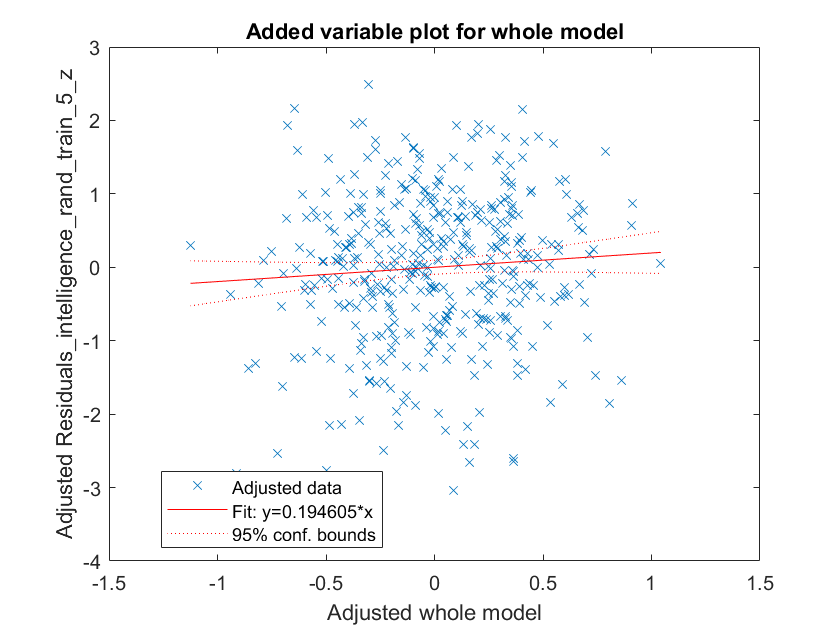

Model_Matrix = [residuals_pos_train_5_z residuals_neg_train_5_z residuals_intelligence_train_5_rand_z];
Model_Matrix = num2cell(Model_Matrix);
Model_Matrix_table = cell2table(Model_Matrix);
Model_Matrix_table.Properties.VariableNames = {'residuals_pos_train_5_z', 'residuals_neg_train_5_z','Residuals_intelligence_rand_train_5_z'};

mdl_pos_neg_bcs_train_5_rand = fitlm(Model_Matrix_table);
plot(mdl_pos_neg_bcs_train_5_rand);

**2. Predict the intelligence scores in the test samples **

2.1. Test Sample 1 

Get data from lockbox sample 

Age_test_1 = Age_lockbox;
Gender_test_1 = Gender_lockbox;
meanFDJenk_test_1 = meanFDJenk_lockbox;
LQ_test_1 = LQ_lockbox;

Intelligence_test_1 = Intelligence_lockbox;

Get the raw residuals by subtracting the fitted values from the observed values (using regression model from above)

confounds = [Age_test_1 Gender_test_1 meanFDJenk_test_1 LQ_test_1];
intelligence_pred_test_1 = predict(mdl_regress_train_1_intelligence_rand,confounds);

residuals_intelligence_test_1 = (Intelligence_test_1 - intelligence_pred_test_1);
residuals_intelligence_test_1_z = normalize(residuals_intelligence_test_1,"center",c_intelligence_train_1,"scale",s_intelligence_train_1);

Retrieve NMAs

Best_case_scenario_r_values_pos = Best_case_scenario_test_samples{1,1};
Best_case_scenario_r_values_neg = Best_case_scenario_test_samples{1,2};

Take the mean per subject

Positive_all = nanmean(Best_case_scenario_r_values_pos,2);
Negative_all = nanmean(Best_case_scenario_r_values_neg,2);

Regress out the confounding variables  and normalize the residuals 

confounds = [Age_test_1 Gender_test_1 meanFDJenk_test_1 LQ_test_1];


Positive_all_pred_test_1 = predict(mdl_regress_train_1_pos_bcs,confounds);

residuals_pos_test_1 = (Positive_all - Positive_all_pred_test_1);
residuals_pos_test_1_z = normalize(residuals_pos_test_1,"center",c_pos_NMA_train_1,"scale",s_pos_NMA_train_1);


Negative_all_pred_test_1 = predict(mdl_regress_train_1_neg_bcs,confounds);

residuals_neg_test_1 = (Negative_all - Negative_all_pred_test_1);
residuals_neg_test_1_z = normalize(residuals_neg_test_1,"center",c_neg_NMA_train_1,"scale",s_neg_NMA_train_1);

Xnew = [residuals_pos_test_1_z residuals_neg_test_1_z];
ypred1_rand = predict(mdl_pos_neg_bcs_train_1_rand,Xnew);

[r_model_1_rand,pval] = corr(ypred1_rand,residuals_intelligence_test_1_z);

2.2. Test Sample 2 

Get data from lockbox sample 

Age_test_2 = Age_lockbox;
Gender_test_2 = Gender_lockbox;
meanFDJenk_test_2 = meanFDJenk_lockbox;
LQ_test_2 = LQ_lockbox;

Intelligence_test_2 = Intelligence_lockbox;

Get the raw residuals by subtracting the fitted values from the observed values (using regression model from above)

confounds = [Age_test_2 Gender_test_2 meanFDJenk_test_2 LQ_test_2];
intelligence_pred_test_2 = predict(mdl_regress_train_2_intelligence_rand,confounds);

residuals_intelligence_test_2 = (Intelligence_test_2 - intelligence_pred_test_2);
residuals_intelligence_test_2_z = normalize(residuals_intelligence_test_2,"center",c_intelligence_train_2,"scale",s_intelligence_train_2);

Retrieve NMAs

Best_case_scenario_r_values_pos = Best_case_scenario_test_samples{2,1};
Best_case_scenario_r_values_neg = Best_case_scenario_test_samples{2,2};

Take the mean per subject

Positive_all = nanmean(Best_case_scenario_r_values_pos,2);
Negative_all = nanmean(Best_case_scenario_r_values_neg,2);

Regress out the confounding variables 

confounds = [Age_test_2 Gender_test_2 meanFDJenk_test_2 LQ_test_2];

Positive_all_pred_test_2 = predict(mdl_regress_train_2_pos_bcs,confounds);

residuals_pos_test_2 = (Positive_all - Positive_all_pred_test_2);
residuals_pos_test_2_z = normalize(residuals_pos_test_2,"center",c_pos_NMA_train_2,"scale",s_pos_NMA_train_2);

Negative_all_pred_test_2 = predict(mdl_regress_train_2_neg_bcs,confounds);

residuals_neg_test_2 = (Negative_all - Negative_all_pred_test_2);
residuals_neg_test_2_z = normalize(residuals_neg_test_2,"center",c_neg_NMA_train_2,"scale",s_neg_NMA_train_2);

Xnew = [residuals_pos_test_2_z residuals_neg_test_2_z];
ypred2_rand = predict(mdl_pos_neg_bcs_train_2_rand,Xnew);

[r_model_2_rand,pval] = corr(ypred2_rand,residuals_intelligence_test_2_z);

2.3. Test Sample 3 

Get data from lockbox sample 

Age_test_3 = Age_lockbox;
Gender_test_3 = Gender_lockbox;
meanFDJenk_test_3 = meanFDJenk_lockbox;
LQ_test_3 = LQ_lockbox;

Intelligence_test_3 = Intelligence_lockbox;

Get the raw residuals by subtracting the fitted values from the observed values (using regression model from above)

confounds = [Age_test_3 Gender_test_3 meanFDJenk_test_3 LQ_test_3];
intelligence_pred_test_3 = predict(mdl_regress_train_3_intelligence_rand,confounds);

residuals_intelligence_test_3 = (Intelligence_test_3 - intelligence_pred_test_3);
residuals_intelligence_test_3_z = normalize(residuals_intelligence_test_3,"center",c_intelligence_train_3,"scale",s_intelligence_train_3);

Retrieve NMAs

Best_case_scenario_r_values_pos = Best_case_scenario_test_samples{3,1};
Best_case_scenario_r_values_neg = Best_case_scenario_test_samples{3,2};

Take the mean per subject

Positive_all = nanmean(Best_case_scenario_r_values_pos,2);
Negative_all = nanmean(Best_case_scenario_r_values_neg,2);

Regress out the confounding variables 

confounds = [Age_test_3 Gender_test_3 meanFDJenk_test_3 LQ_test_3];

Positive_all_pred_test_3 = predict(mdl_regress_train_3_pos_bcs,confounds);

residuals_pos_test_3 = (Positive_all - Positive_all_pred_test_3);
residuals_pos_test_3_z = normalize(residuals_pos_test_3,"center",c_pos_NMA_train_3,"scale",s_pos_NMA_train_3);

Negative_all_pred_test_3 = predict(mdl_regress_train_3_neg_bcs,confounds);

residuals_neg_test_3 = (Negative_all - Negative_all_pred_test_3);
residuals_neg_test_3_z = normalize(residuals_neg_test_3,"center",c_neg_NMA_train_3,"scale",s_neg_NMA_train_3);

Xnew = [residuals_pos_test_3_z residuals_neg_test_3_z];
ypred3_rand = predict(mdl_pos_neg_bcs_train_3_rand,Xnew);

[r_model_3_rand,pval] = corr(ypred3_rand,residuals_intelligence_test_3_z);

2.4. Test Sample 4 

Get data from lockbox sample 

Age_test_4 = Age_lockbox;
Gender_test_4 = Gender_lockbox;
meanFDJenk_test_4 = meanFDJenk_lockbox;
LQ_test_4 = LQ_lockbox;

Intelligence_test_4 = normalize(Intelligence_lockbox);


Get the raw residuals by subtracting the fitted values from the observed values (using regression model from above)

confounds = [Age_test_4 Gender_test_4 meanFDJenk_test_4 LQ_test_4];
intelligence_pred_test_4 = predict(mdl_regress_train_4_intelligence_rand,confounds);

residuals_intelligence_test_4 = (Intelligence_test_4 - intelligence_pred_test_4);
residuals_intelligence_test_4_z = normalize(residuals_intelligence_test_4,"center",c_intelligence_train_4,"scale",s_intelligence_train_4);

Retrieve NMAs

Best_case_scenario_r_values_pos = Best_case_scenario_test_samples{4,1};
Best_case_scenario_r_values_neg = Best_case_scenario_test_samples{4,2};

Take the mean per subject

Positive_all = nanmean(Best_case_scenario_r_values_pos,2);
Negative_all = nanmean(Best_case_scenario_r_values_neg,2);

Regress out the confounding variables and normalize the residuals 

confounds = [Age_test_4 Gender_test_4 meanFDJenk_test_4 LQ_test_4];

Positive_all_pred_test_4 = predict(mdl_regress_train_4_pos_bcs,confounds);

residuals_pos_test_4 = (Positive_all - Positive_all_pred_test_4);
residuals_pos_test_4_z = normalize(residuals_pos_test_4,"center",c_pos_NMA_train_4,"scale",s_pos_NMA_train_4);

Negative_all_pred_test_4 = predict(mdl_regress_train_4_neg_bcs,confounds);

residuals_neg_test_4 = (Negative_all - Negative_all_pred_test_4);
residuals_neg_test_4_z = normalize(residuals_neg_test_4,"center",c_neg_NMA_train_4,"scale",s_neg_NMA_train_4);

Xnew = [residuals_pos_test_4_z residuals_neg_test_4_z];
ypred4_rand = predict(mdl_pos_neg_bcs_train_4_rand,Xnew);


[r_model_4_rand,pval] = corr(ypred4_rand,residuals_intelligence_test_4_z);

2.5. Test Sample 5 

Get data from lockbox sample 

Age_test_5 = Age_lockbox;
Gender_test_5 = Gender_lockbox;
meanFDJenk_test_5 = meanFDJenk_lockbox;
LQ_test_5 = LQ_lockbox;

Intelligence_test_5 = Intelligence_lockbox;

Get the raw residuals by subtracting the fitted values from the observed values (using regression model from above)

confounds = [Age_test_5 Gender_test_5 meanFDJenk_test_5 LQ_test_5];
intelligence_pred_test_5 = predict(mdl_regress_train_5_intelligence_rand,confounds);

residuals_intelligence_test_5 = (Intelligence_test_5 - intelligence_pred_test_5);
residuals_intelligence_test_5_z = normalize(residuals_intelligence_test_5,"center",c_intelligence_train_5,"scale",s_intelligence_train_5);

Retrieve NMAs

Best_case_scenario_r_values_pos = Best_case_scenario_test_samples{5,1};
Best_case_scenario_r_values_neg = Best_case_scenario_test_samples{5,2};

Take the mean per subject

Positive_all = nanmean(Best_case_scenario_r_values_pos,2);
Negative_all = nanmean(Best_case_scenario_r_values_neg,2);

Regress out the confounding variables 

confounds = [Age_test_5 Gender_test_5 meanFDJenk_test_5 LQ_test_5];

Positive_all_pred_test_5 = predict(mdl_regress_train_5_pos_bcs,confounds);

residuals_pos_test_5 = (Positive_all - Positive_all_pred_test_5);
residuals_pos_test_5_z = normalize(residuals_pos_test_5,"center",c_pos_NMA_train_5,"scale",s_pos_NMA_train_5);

Negative_all_pred_test_5 = predict(mdl_regress_train_5_neg_bcs,confounds);

residuals_neg_test_5 = (Negative_all - Negative_all_pred_test_5);
residuals_neg_test_5_z = normalize(residuals_neg_test_5,"center",c_neg_NMA_train_5,"scale",s_neg_NMA_train_5);

Xnew = [residuals_pos_test_5_z residuals_neg_test_5_z];
ypred5_rand = predict(mdl_pos_neg_bcs_train_5_rand,Xnew);

[r_model_5_rand,pval] = corr(ypred5_rand,residuals_intelligence_test_5_z);

**3.  Take the average of the performance from the 5 models **

correlations_5_rand_models = [r_model_1_rand r_model_2_rand r_model_3_rand r_model_4_rand r_model_5_rand];

z_scores_correlation_5_random_models = atanh(correlations_5_rand_models);

average_z_scores_correlation_5_random_models = mean(z_scores_correlation_5_random_models);

average_correlation_5_random_models_final = tanh(average_z_scores_correlation_5_random_models);

**4. Save rho_final & pval_final for permutation test **

Permutation_test_all_cross_val_rounds_rho{cross_validation_round,permutation_test_round} = average_correlation_5_random_models_final;

**End permutation test**

end

end

**4. Analysis Section**

all_rhos_final_correlations = cell2mat(cross_validation_100_final_correlation_HCP(:,1))

all_rhos_final_correlations = 100×1
    0.1425
    0.1287
    0.1349
    0.1320
    0.1343
    0.1368
    0.1316
    0.1220
    0.1218
    0.1274



all_rhos_final_correlations_z_scores = atanh(all_rhos_final_correlations);

mean_all_rhos_final_correlations_z_score = mean(all_rhos_final_correlations_z_scores);

mean_all_rhos_final_correlations_final = tanh(mean_all_rhos_final_correlations_z_score)

mean_all_rhos_final_correlations_final = 0.1295


Permutation_test_all_cross_val_rounds_rho_mat = cell2mat(Permutation_test_all_cross_val_rounds_rho);

find(Permutation_test_all_cross_val_rounds_rho_mat > mean_all_rhos_final_correlations_final) 

ans = 2×1
    65
   852


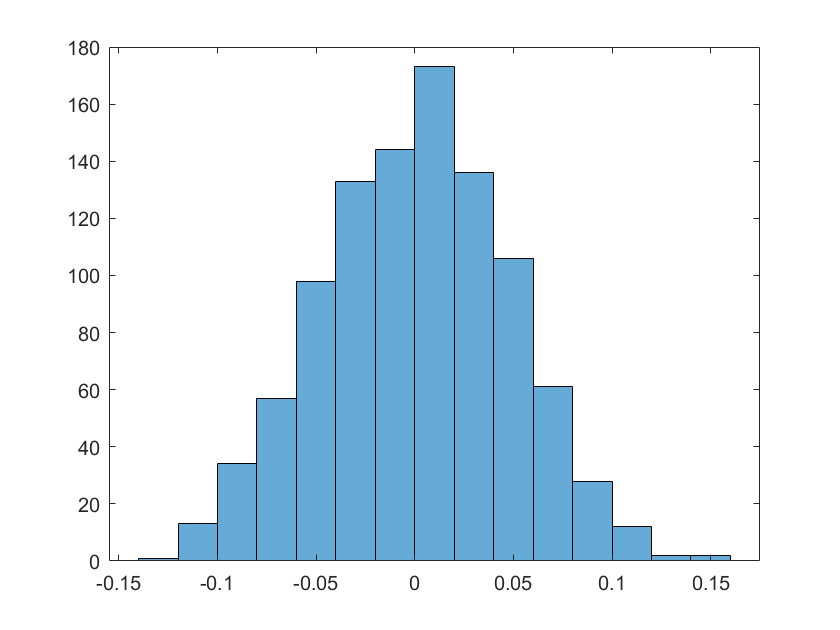

histogram(Permutation_test_all_cross_val_rounds_rho_mat)